# Driver Script to Make  Rt Heatmap

This Script runs the model based on the inputted test_conditions and freq_conditions. 

    Test_conditions: number of tests randomly given to the student body

    Freq_conditions: Frequency of the tests being given

This script allows you to input your scenario of choice (listed in the Scenarios_makeHeatmapRt Folder). 

%Number of tests being administered
tests_conditions=[500,2500:2500:10000];

%Frequency of the Test Administration
freq_conditions=[1:7,14];

% Number of times simulation runs
iterationsize = 1; 

#### Run The Simulation based on the Number of Tests and Frequency 

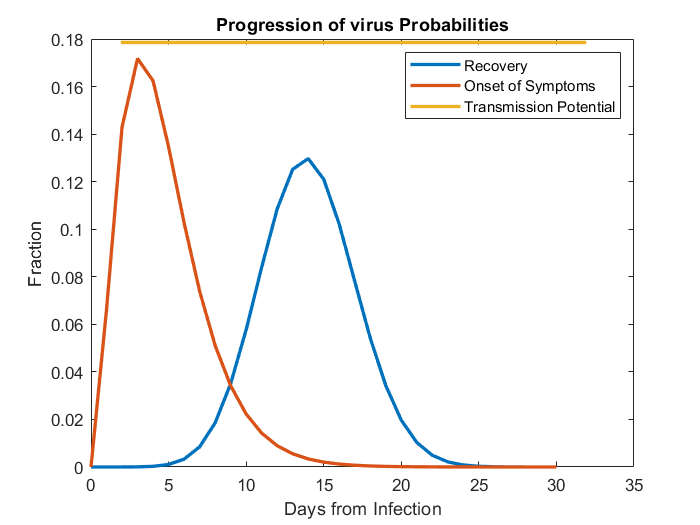

maskfactor = 0.3300

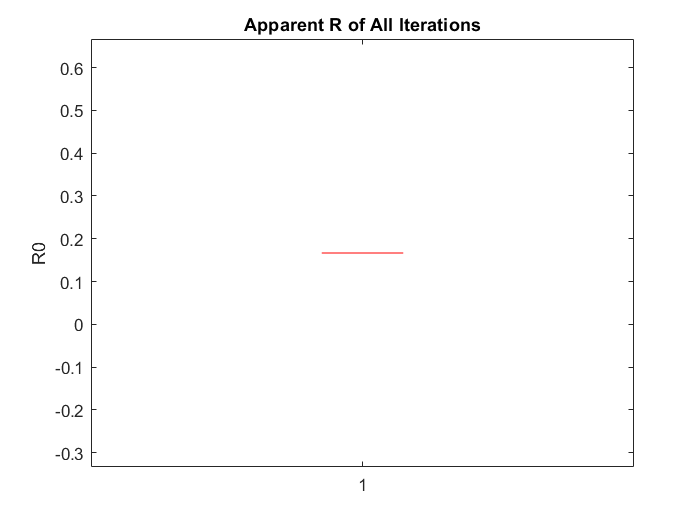

r0_all =     0.1667    2.4731    2.5113    2.4854    2.4930


maskfactor = 0.3300

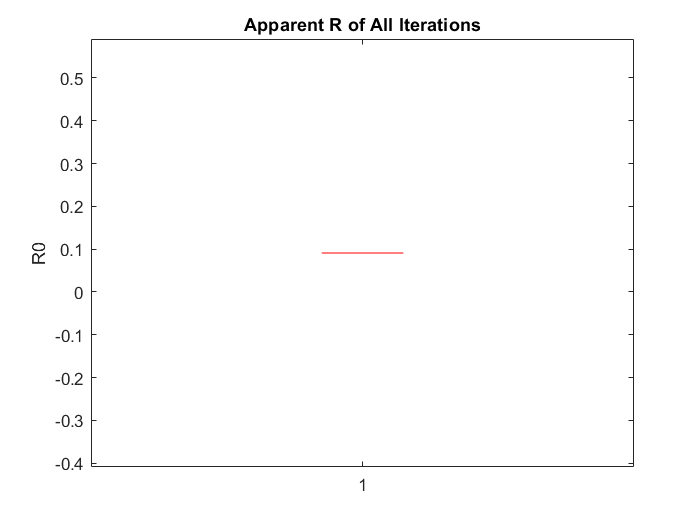

r0_all =     0.1667    0.0909    2.5113    2.4854    2.4930


maskfactor = 0.3300

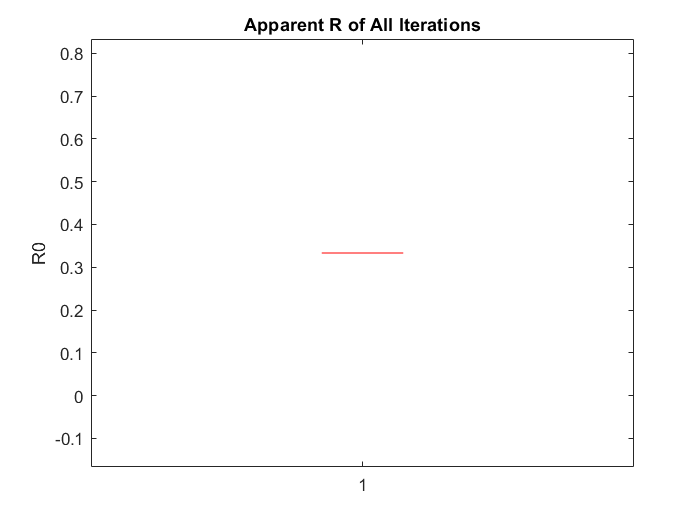

r0_all =     0.1667    0.0909    0.3333    2.4854    2.4930


maskfactor = 0.3300

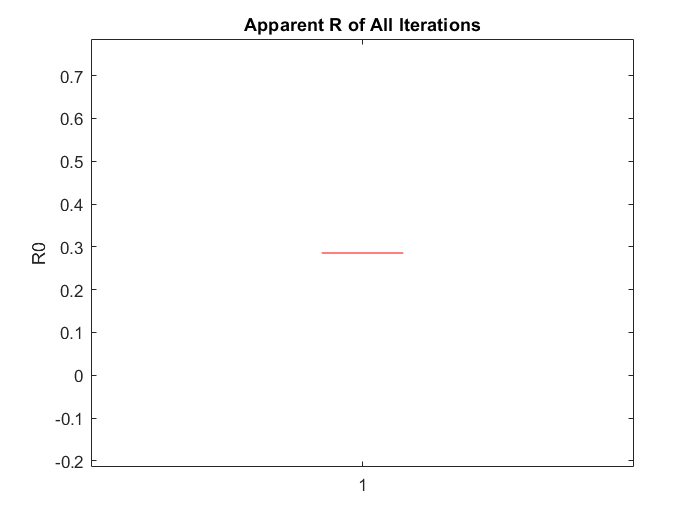

r0_all =     0.1667    0.0909    0.3333    0.2857    2.4930


maskfactor = 0.3300

r0_all =     0.1667    0.0909    0.3333    0.2857    0.2857


%For each Number of Test
for z=1:size(tests_conditions,2)
    
    %Assign the approproate number of tests
    numtest=tests_conditions(z);
    
    %For each Frequency of Test
    for y=1:size(freq_conditions,2)
        
        %clear the students array produced by the model
        clear students
        
        %Assign the appropriate frequency of tests
        testfreq=freq_conditions(y);
        
        %Add the folder which stores all the model scenarios
        addpath Scenarios_makeHeatmapRt\
       
        %Below, input your scenario of choice
        Scenario1_PerfectTestsUniformSpread
 
        %Store the median Rt produced by the many iterations of the model 
        rt_all(z,y)=median(rtsample)
        
        %Sort the Rts in increasing order
        rt_sorted=sort(rtsample);
        
        %Find the 95th Percentile based on iteration size 
        % and the sorted Rt
        rt_upper95(z,y)=rt_sorted(ceil(iterationsize*0.95));
    end
end

### Create a Heatmap of the Rt Medians and 95th Percentile

figure();
%Colormap to show Rt<1 is blue and Rt>1 Yellow/Red
map=[0, 0, 0.05; 0, 0, 0.2; 0, 0, 0.35; 0, 0, 0.5;0, 0, 0.65; 0, 0, 0.8;0, 0, 0.95;0, 0, 1.0;...
    1.0000,1,0;1.0000,0.92,0;1.0000,0.84,0;1.0000,0.76,0;1.0000,0.68,0;1.0000,0.60,0;1.0000,0.52,0;1.0000,0.44,0;...
    1.0000,0.36,0;1.0000,0.28,0;1.0000,0.20,0;1.0000,0.12,0];


The first Subplot is the Median Rt from the iterations run above

subplot(2,1,1)
h=heatmap( rt_all,'colorlimits',[0,2.5],'Colormap',map,...
        'YData',string(tests_conditions/100)+'%', 'Xdata', string(freq_conditions),...
        'FontSize', 7);
h.CellLabelFormat = '%.2f';
title('Rt Median') %title
xlabel('Test Frequency (days)') %x axis label
ylabel('Percentage of Students Tested') %y axis label
        

 The second subplot is the 95th percentile of the iterations run above

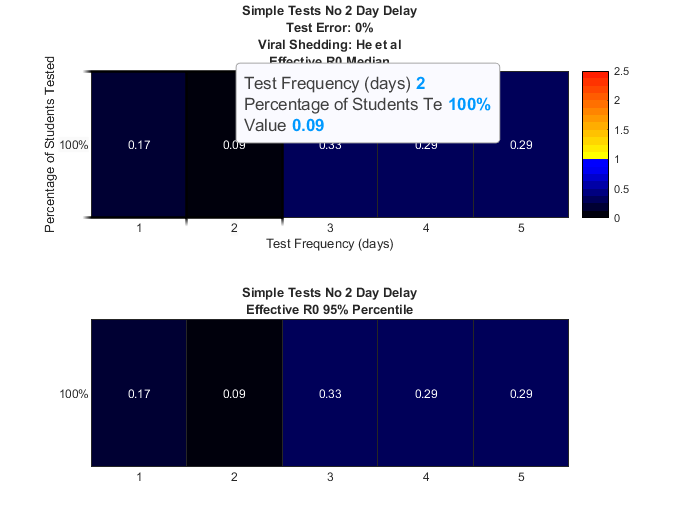

 subplot(2,1,2)
 h=heatmap(rt_upper95,'colorlimits',[0,2.5],'Colormap',map,...
        'YData',string(tests_conditions/100)+'%', 'Xdata', string(freq_conditions),...
        'FontSize', 7,'ColorbarVisible','off');
 title('Rt 95% Percentile')
 h.CellLabelFormat = '%.2f';

 xlabel('Test Frequency (days)') %x axis label
 ylabel('Percentage of Students Tested') %y axis label

